## **Read & Display Image**

**       Part  A. read an image (*) into a workspace variable.**

**        Part B. display the image.**

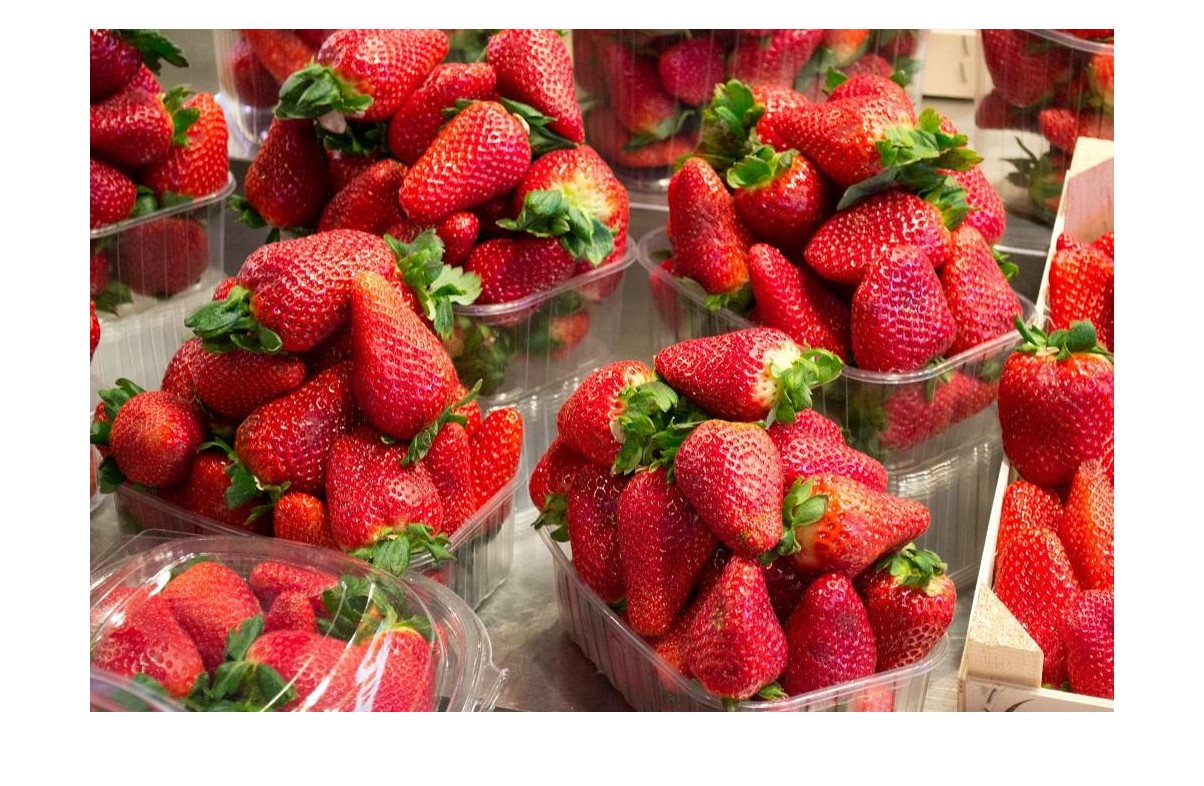


% change directory folder to pick images from
path= 'C:\Users\shukl\Documents\GitHub\COT5930-Image-Processing\Assignment1\Input_Images\';
cd (path)
file_names = dir('**/');
file_names = file_names(~[file_names.isdir]);
file_names = string({file_names.name})';

% select Image from using drop down
Selected_Image=file_names(5);

% Read and display the image
Input_Image=strcat(path,Selected_Image);
A=imread(Input_Image);
imshow(A)

## **Apply Effects and Display Results**

**        Part C. apply an image processing filter/effect of your choice (**) to the image.**

**        Part D. display the result.**

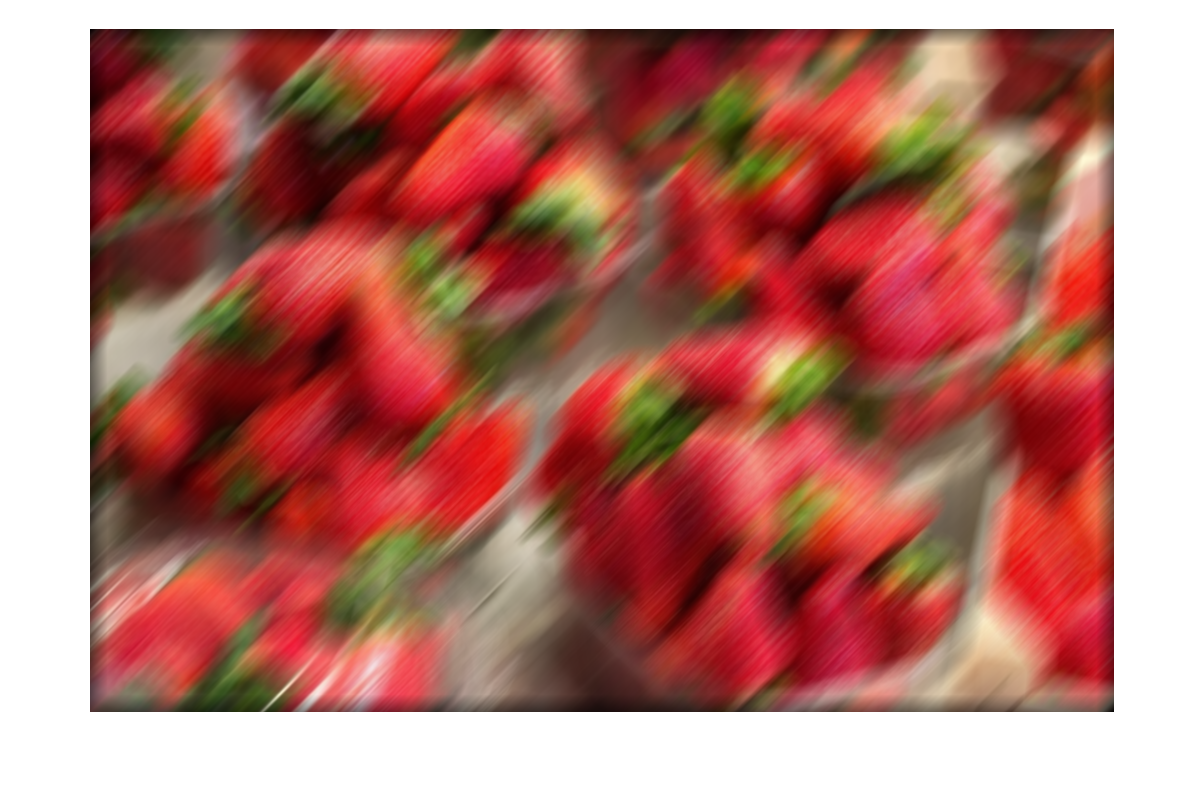

% parameter for blur filter
h = fspecial('motion', 50, 45);

% select effect to be performed on image
effects="imfilter(A,h)";

% apply the effect and show the new image
B=eval(effects);
imshow(B)

## Save the Output

**         Part E. save the resulting image to a .png or any other format file.**

% select the desired format for saving the new image
save_format=".jpg";

% Create new file name
[~,name,~] = fileparts(Selected_Image);
newfile=strcat(name,'_new',save_format);

%change directory to location where image has to be saved
cd 'C:\Users\shukl\Documents\GitHub\COT5930-Image-Processing\Assignment1\Output_Images\'

% save image in desired format
imwrite(B,newfile)

